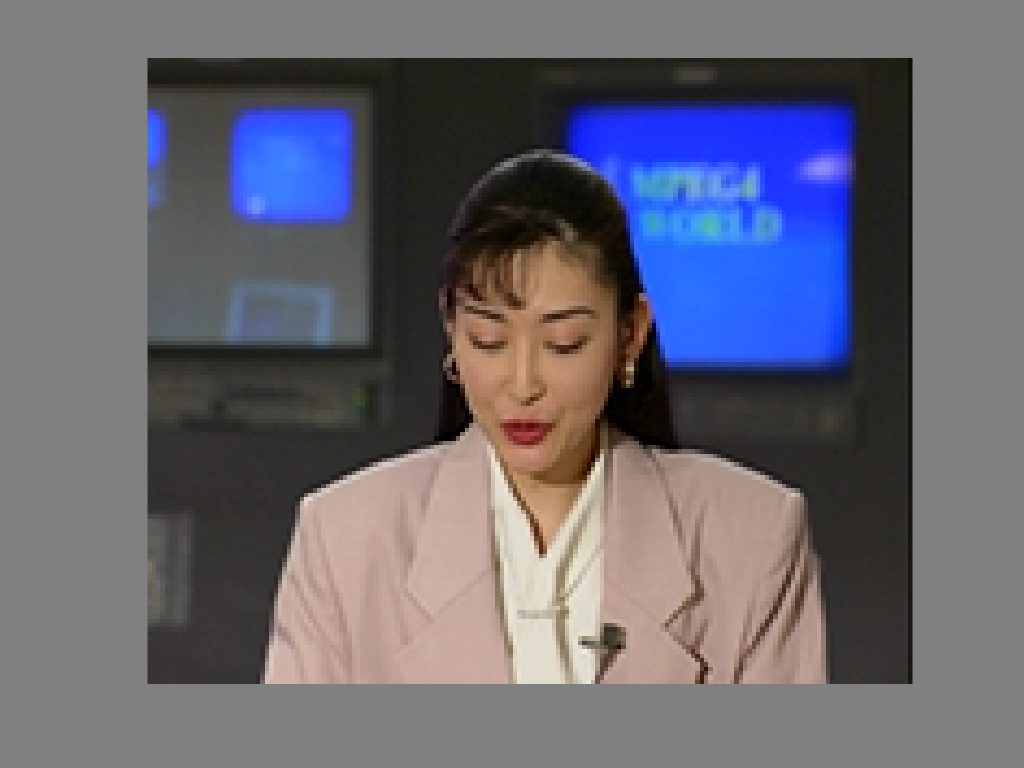

filename = 	'akiyo_qcif.y4m';

fid = fopen(filename,'r');
%reading data from the beginning of the file:
datavector=fread(fid,100,'uint8');
fclose(fid);	

%pre-processing the header
headerline=char(datavector');
keyword='FRAME';
index=strfind(headerline,keyword);
%read only the header
header=headerline(1:index-2);
	
% find W, H, F, I, A and C variables from header 
fields = {'W', 'H', 'F', 'I', 'A', 'C'};
c = cell(length(fields),1);
parameters = cell2struct(c,fields);

space_ind = find(header==' ');

value = 'W';
data_ind = find(header == value);
next_space = space_ind(find(space_ind > data_ind, 1));
if isempty(next_space)
    param_data = header(data_ind + 1:end);
else
    param_data = header(data_ind + 1:next_space - 1);
end
parameters.W = str2num(param_data);

value = 'H';
data_ind = find(header == value);
next_space = space_ind(find(space_ind > data_ind, 1));
if isempty(next_space)
    param_data = header(data_ind + 1:end);
else
    param_data = header(data_ind + 1:next_space - 1);
end
parameters.H = str2num(param_data);

value = 'F';
data_ind = find(header == value);
next_space = space_ind(find(space_ind > data_ind, 1));
if isempty(next_space)
    param_data = header(data_ind + 1:end);
else
    param_data = header(data_ind + 1:next_space - 1);
end
parameters.F = param_data;

value = 'I';
data_ind = find(header == value);
next_space = space_ind(find(space_ind > data_ind, 1));
if isempty(next_space)
    param_data = header(data_ind + 1:end);
else
    param_data = header(data_ind + 1:next_space - 1);
end
parameters.I = param_data;

value = 'A';
data_ind = find(header == value);
next_space = space_ind(find(space_ind > data_ind, 1));
if isempty(next_space)
    param_data = header(data_ind + 1:end);
else
    param_data = header(data_ind + 1:next_space - 1);
end
parameters.A = param_data;

value = 'C';
data_ind = find(header == value);
if isempty(data_ind)
    param_data = num2str(420);
else
    next_space = space_ind(find(space_ind > data_ind, 1));
    if isempty(next_space)
        param_data = header(data_ind + 1:end);
    else
        param_data = header(data_ind + 1:next_space - 1);
    end
end
parameters.C = param_data;

% read the image data for processing:

leveys = parameters.W;
korkeus = parameters.H;

Nmax=50;    %number of frames to read max
fid = fopen(filename,'r');  %open the file
keyword='FRAME';    %the frame tag to search for

%computing the segment length:
segmentlength = (korkeus*leveys*1.5)+length(keyword)+1;

%searching the first index
firstindex=strfind(char(datavector)',keyword);
	
%variable for locations, first column defines index number, second the location
locations=[1 2];
	
%searching the frame locations:
for frameindex=1 : Nmax
   location=(frameindex-1)*segmentlength+firstindex;
   locations=cat(1,locations,[frameindex location]); %collect the frame locations to 2 x Nmax vector
end

%the first location is false and thus left out
locations=locations(2:end,:);


figure(1)
posvec=[50 150 1024 768];
figure('Color',[0.5 0.5 0.5],'Position',posvec) 

%reading the image data from frame 1
for frameindex=1:Nmax;
    sijainti = locations(frameindex,2)+length(keyword);
    [rgbkuva] = luekuva(fid, sijainti, korkeus, leveys);
    imagehandle=image(rgbkuva);
    axis equal; axis off;
    set(imagehandle,'Cdata',rgbkuva); drawnow; 
    pause(0.1)
end